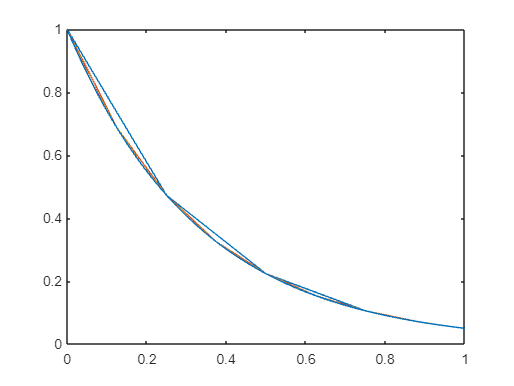

maxit = 16;
H = zeros(maxit,1);

for n = 1:maxit
    h = 2^(-n);
    H(n) = 2^(-n);
    a = 0;
    b = 1;
    y0 = 1;
    TOL = 10^(-6);
    
    T = zeros(1,2^n);
    Y = zeros(1,n);
    t = a;
    
    %y is for RK4, z is for RK5
    y = y0;
    
    T(1) = t;
    Y(:,1) = y;
    
    for i = 2:2^n
        %Computing increments for RK45
        k1 = h*f(t,y); 
        k2 = h*f(t+h/4, y+k1/4);
        k3 = h*f(t+(3/8)*h,y+(3/32)*k1+(9/32)*k2);
        k4 = h*f(t+(12/13)*h,y+(1932/2197)*k1-(7200/2197)*k2+(7296/2197)*k3);
        k5 = h*f(t+h,y+(439/216)*k1-(8)*k2+(3680/513)*k3-(845/4104)*k4);
        k6 = h*f(t+h/2,y-(8/27)*k1+(2)*k2-(3544/2565)*k3+(1859/4104)*k4-(11/40)*k5);
        
        %RK4 or RK5 approximation of Y(i)
        Y(:,i) = y+(25/216)*k1+(1408/2565)*k3+(2197/4104)*k4-(1/5)*k5;
        Y(:,i) = y+(16/135)*k1+(6656/12825)*k3+(28561/56430)*k4-(9/50)*k5+(2/55)*k6;

        y = Y(:,i);
        t = t+h;
        T(i) = t;
    end

    if n > 1
        plot(T,Y(1,:))
        hold on
    end

    error(n) = Y(1,end)- exp(-3*T(end));

end

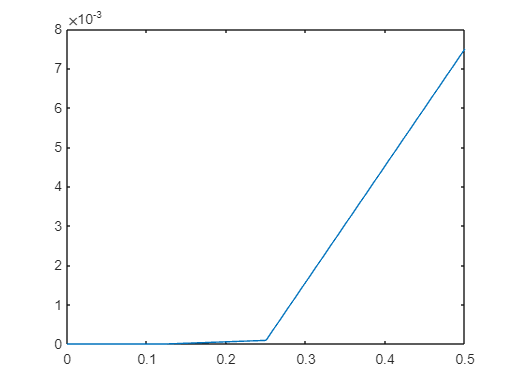


figure
plot(H,abs(error),'DisplayName', 'Error')

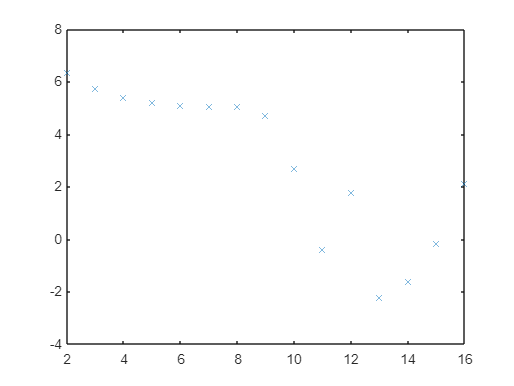


figure
alpha_seq = est_conv_ord(abs(error));
plot(alpha_seq,'x');

function y_prime = f(t,y)
k = -3;
y_prime = k*y;
end

function alpha_seq = est_conv_ord(seq)
    alpha_seq = seq;
    alpha_seq(1) = [NaN];
    for i = 2:length(alpha_seq)
        alpha_seq(i) = (log(seq(i-1))-log(seq(i)))/log(2);
    end
end